# HO-SVD

clear;
clc;

format short g;

% Set seed
% rng(197);
% rng(123);
% rng(111);
rng(1);

**Continuous Complex System**

We consider the 2-parameter complex system, where $f(x_1,x_2)=\Lambda(x_1,x_2)(e \times sin(8x_1) + 5 sin(3x_2))$ when $x_1 < x_2$ and $f(x_1,x_2)=(1-\Lambda(x_1,x_2))(e \times sin(8x_1) + 5 sin(3x_2))$ when $x_1 \geq x_2$. Furthermore, $\Lambda(x_1,x_2)$ is an exponential smoothing term, which smooths the transition, where $x_1 \sim x_2$.

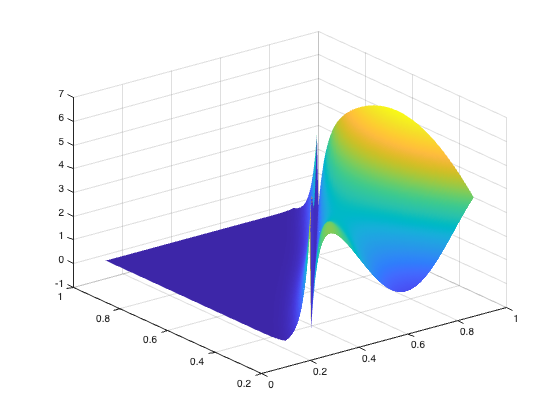

%% Create Space
load Space_Slanted_Border_Function.mat;

surf(X,Y,Space,'EdgeColor','none')

**Default parameters**

In our experiments,

- We set the default per time stamp sampling budget $B^t$ to **0.02%** of the volume of the space.

- The target rank for HO-SVD is set to **25%** of the size of the parameter space.

- The default exploration probability for BFF-RS and GFF-RS is set to **0.15**.

In this particular case, we set the step budget size to **8** new samples.

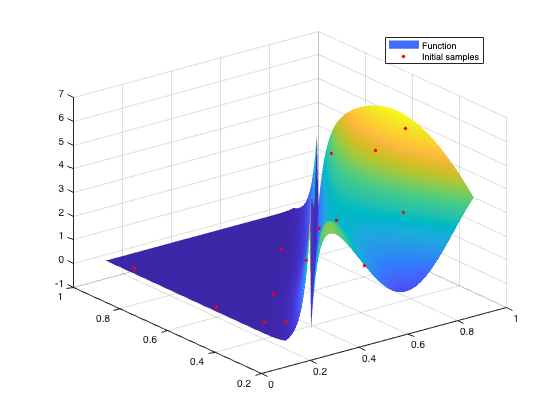

% Volume of the space
dimX = size(X,1);
dimY = size(Y,1);
volume = dimX * dimY;

% Initial budget
budget = ceil(0.0002 * volume);

% Tolerance (for HOSVD calculation)
eps = 0.0002;

% Budget for next iterations
new_budget = 50;  % 9000

alpha = 0.15;

% Initial random samples
samples = randi(dimX,budget,2);
[x,y,s] = create_samples(X,Y,Space,samples);

draw_samples(X,Y,Space,x,y,s);

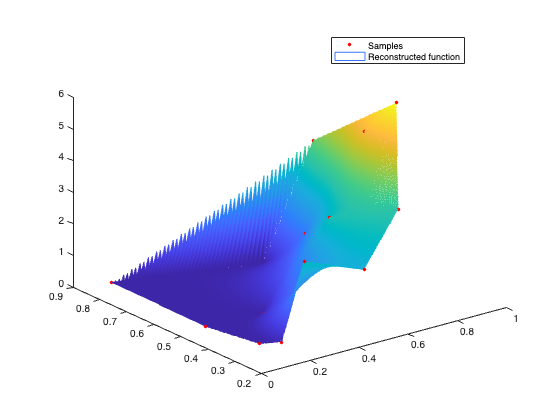

draw_interpolation(X,Y,x,y,s);

With only 14 points, the approximation to the original function is very bad.

% Create sparse tensor
T = sptensor(samples,s',[dimX dimY]);

T_full = full(T);  % Dense tensor
% T_doub = double(T_full);

% HOSVD estimation
decom = hosvd(T_full,2*sqrt(eps));  % 'verbosity',0

Computing HOSVD...
Size of core: 8 x 8
||X-T||/||X|| = 0.0140773 <=0.028284 (tol)



% Compute HOSVD with desired relative error = 0.1
% T = hosvd(X,0.1);

% Check size of core
% coresize = size(T.core)

% Check relative error
% relerr = norm(X-full(T))/norm(X)

%Factor matrices (U,V,W) and core tensor
core=decom.core;
G=double(core);
U=decom.U{1};
V=decom.U{2};
% W=decom.U{3};

## SAMPLE SELECTION STRATEGIES

% decom_doub = double(decom);
tensor_recon = full(decom);

fit = calculate_fit(T_full,decom);

In this case, we calculate the degree of fit of each pivot (actually it is the loss) as:


$$loss(x^t) = abs(x^t-\hat{x}^t)$$


Where $x^t$ is the pivot entry and $\hat{x}^t$ is the reconstructed version of that entry.

### BAD FIT FIRST

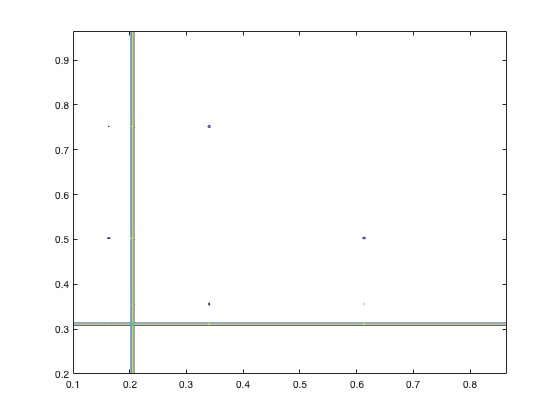

[row,col,~,prob_mat] = create_new_samples(X,Y,Space, ...
    T_full,tensor_recon,samples, ...
    new_budget,'bff',0);

% disp(losses')
% disp(prob_mat)
% disp([row' col'])

contour(X,Y,prob_mat)

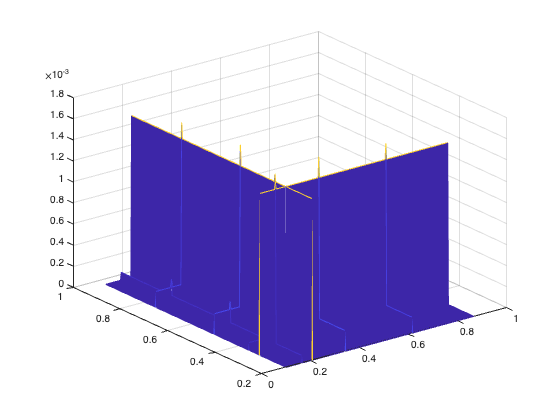

mesh(X,Y,prob_mat)

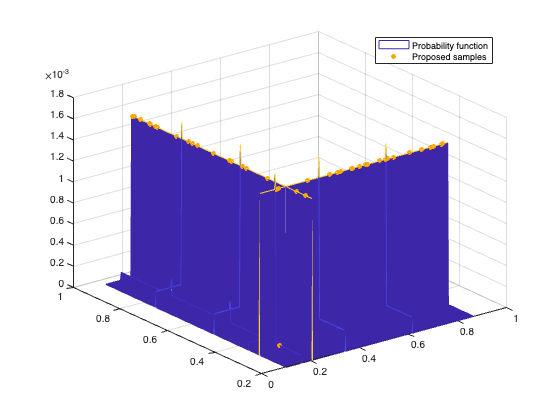

draw_samples_prob(X,Y,prob_mat,[row' col'])

We can see how samples are chosen in areas with low probability.

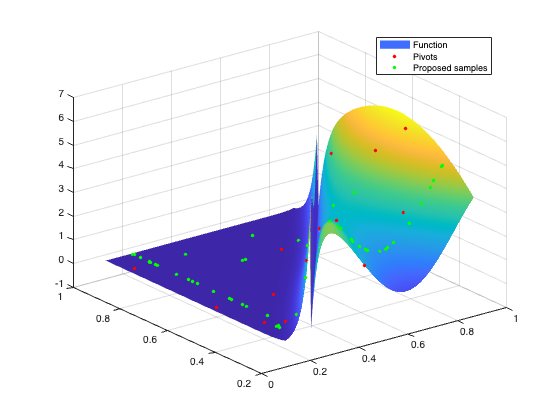

[xn,yn,sn] = create_samples(X,Y,Space,[row' col']);

draw_samples(X,Y,Space,x,y,s,xn,yn,sn);

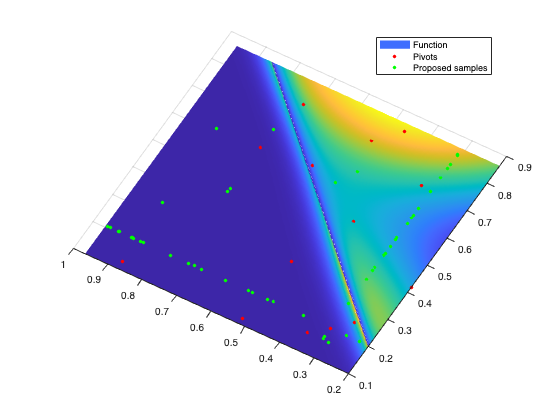

draw_samples(X,Y,Space,x,y,s,xn,yn,sn)
view([-60 90]);

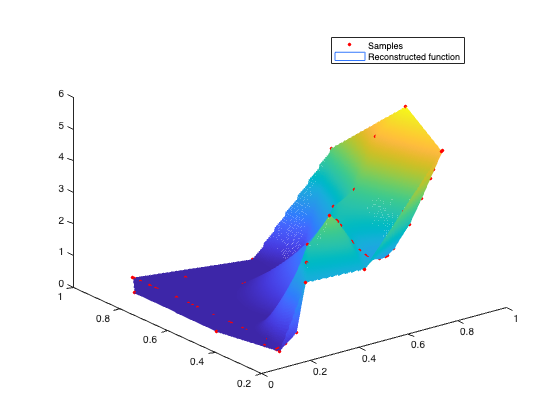

draw_interpolation(X,Y,cat(2,x,xn),cat(2,y,yn),cat(2,s,sn));

The reconstruction of the function is something better than the previous one.

### BFF WITH RANDOM SAMPLING

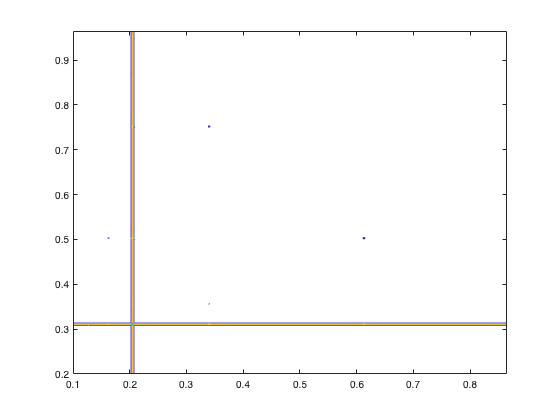

[row,col,~,prob_mat] = create_new_samples(X,Y,Space, ...
    T_full,tensor_recon,samples, ...
    new_budget,'bff',[1 alpha]);

% disp(losses')
% disp(prob_mat)
% disp([row' col'])

contour(X,Y,prob_mat)

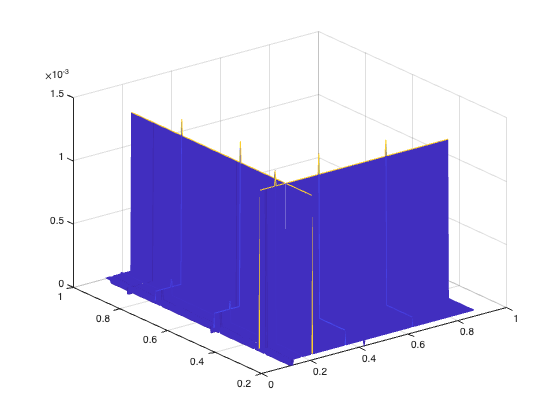

mesh(X,Y,prob_mat)

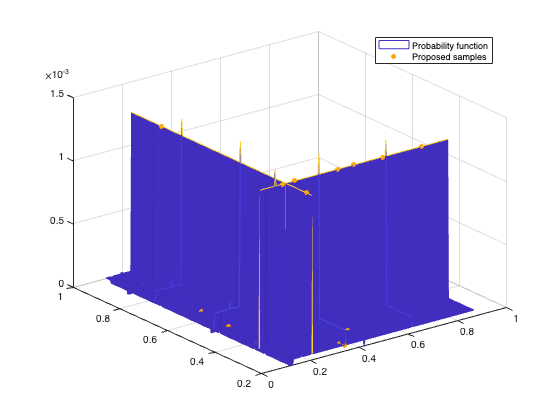

draw_samples_prob(X,Y,prob_mat,[row' col'])

With random sampling, we see that we have samples in places where previously the probability was 0.

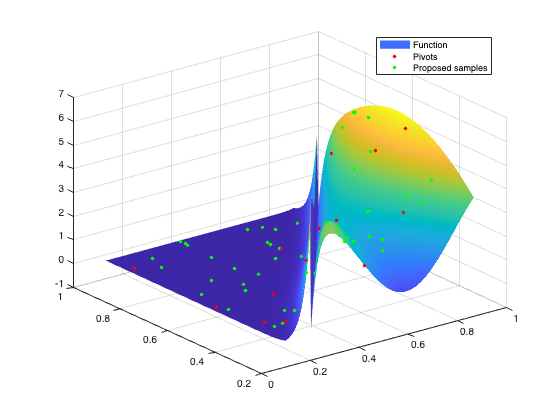

[xn,yn,sn] = create_samples(X,Y,Space,[row' col']);

draw_samples(X,Y,Space,x,y,s,xn,yn,sn);

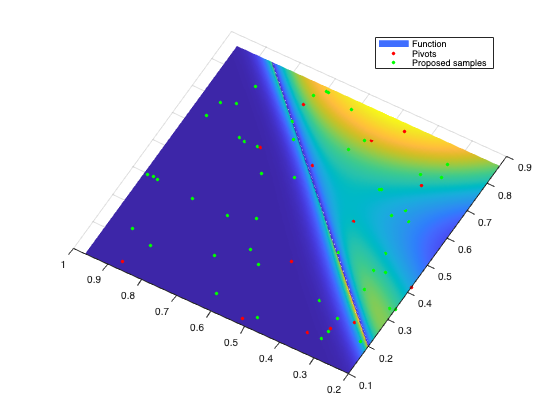

draw_samples(X,Y,Space,x,y,s,xn,yn,sn)
view([-60 90]);

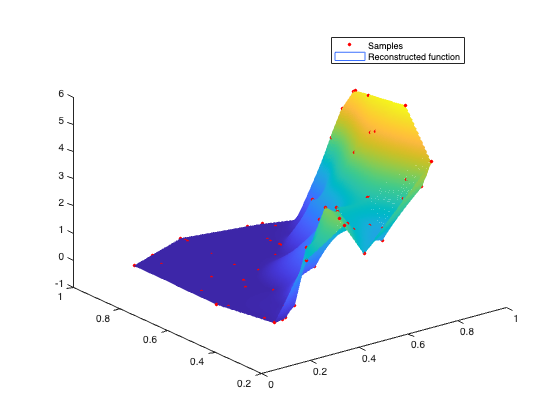

draw_interpolation(X,Y,cat(2,x,xn),cat(2,y,yn),cat(2,s,sn));

The reconstruction of the function is also somewhat better than the original.

### GOOD FIT FIRST

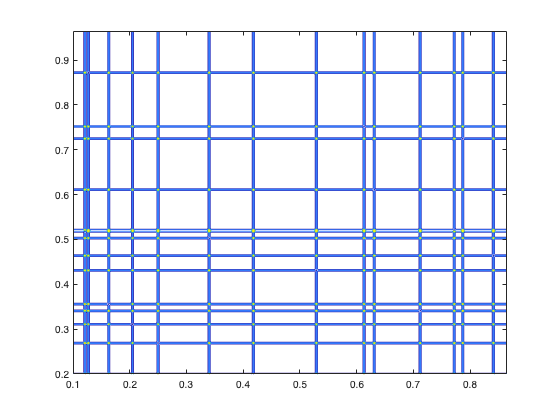

[row,col,~,prob_mat] = create_new_samples(X,Y,Space, ...
    T_full,tensor_recon,samples, ...
    new_budget,'gff',0);

% disp(losses')
% disp(prob_mat)
% disp([row' col'])

contour(X,Y,prob_mat)

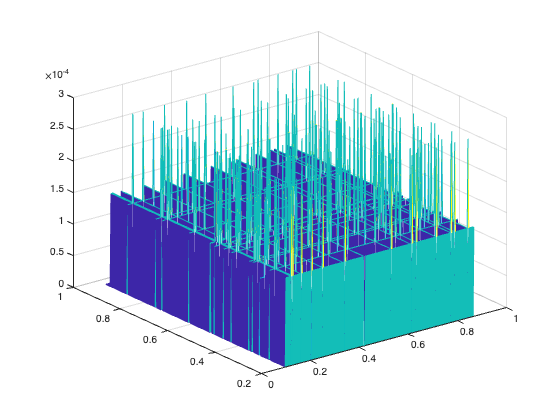

mesh(X,Y,prob_mat)

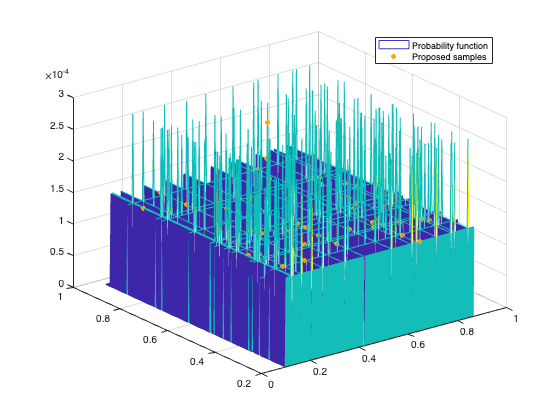

draw_samples_prob(X,Y,prob_mat,[row' col'])

Here we see that there are many more zones with high probability compared to the others, but samples are also created in zones with low probability.

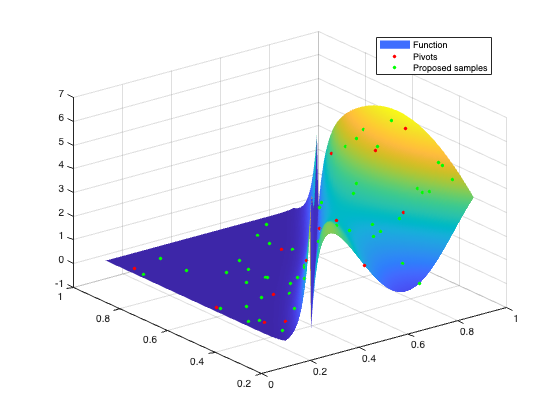

[xn,yn,sn] = create_samples(X,Y,Space,[row' col']);

draw_samples(X,Y,Space,x,y,s,xn,yn,sn);

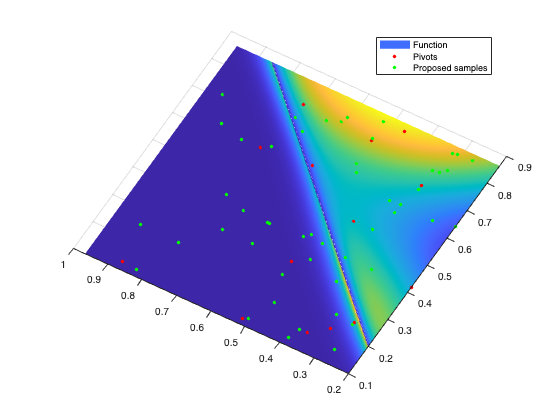

draw_samples(X,Y,Space,x,y,s,xn,yn,sn)
view([-60 90]);

In this case the samples are more spread out.

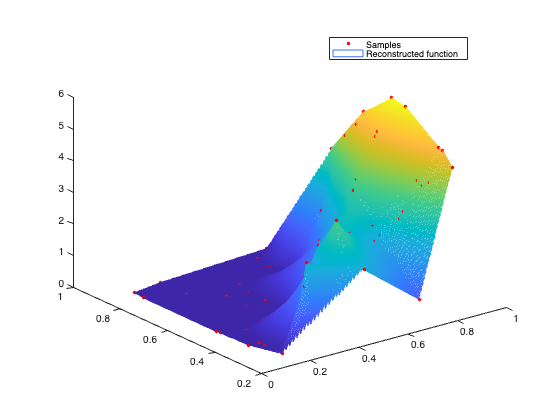

draw_interpolation(X,Y,cat(2,x,xn),cat(2,y,yn),cat(2,s,sn));

As before, the reconstruction is better.

### GFF WITH RANDOM SAMPLING

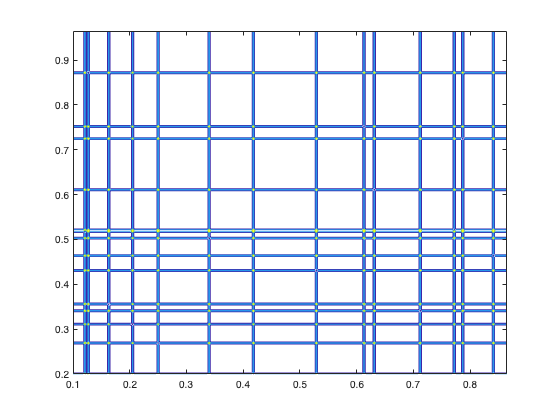

[row,col,~,prob_mat] = create_new_samples(X,Y,Space, ...
    T_full,tensor_recon,samples, ...
    new_budget,'gff',[1 alpha]);

% disp(losses')
% disp(prob_mat)
% disp([row' col'])

contour(X,Y,prob_mat)

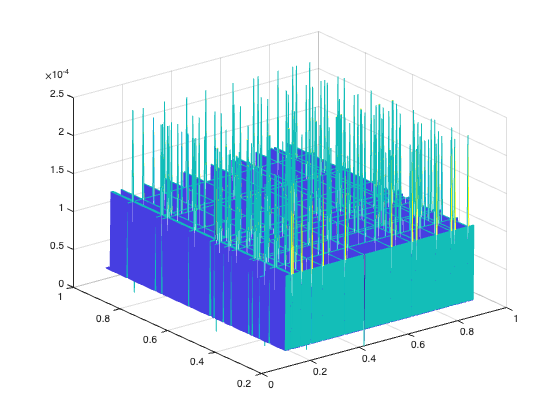

mesh(X,Y,prob_mat)

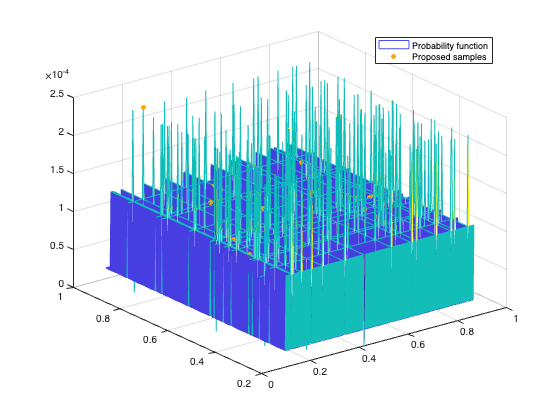

draw_samples_prob(X,Y,prob_mat,[row' col'])

Here the new samples are slightly different from the version without random sampling, although the $\alpha$ parameter should also be adjusted.

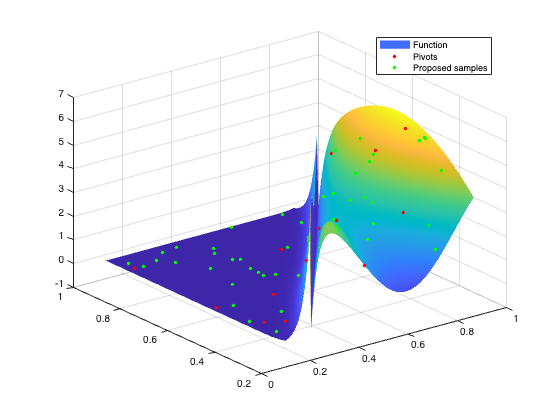

[xn,yn,sn] = create_samples(X,Y,Space,[row' col']);

draw_samples(X,Y,Space,x,y,s,xn,yn,sn);

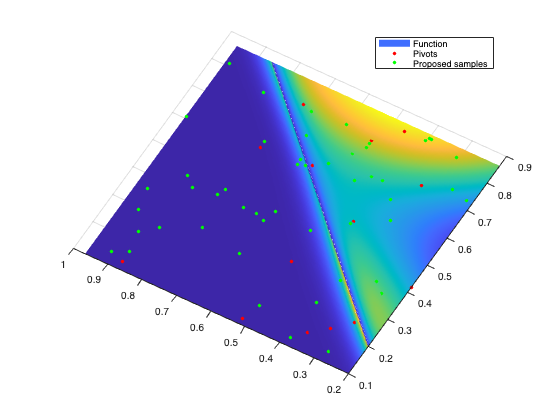

draw_samples(X,Y,Space,x,y,s,xn,yn,sn)
view([-60 90]);

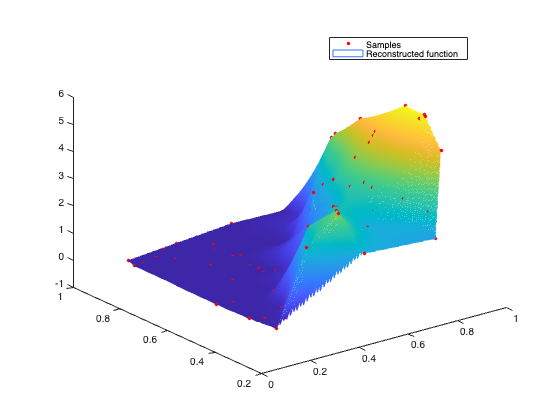

draw_interpolation(X,Y,cat(2,x,xn),cat(2,y,yn),cat(2,s,sn));

In this case, the conclusions are similar to the previous ones.

## HYBRID SAMPLING STRATEGY

[row,col] = create_new_samples(X,Y,Space, ...
    T_full,tensor_recon,samples, ...
    new_budget,'hybrid');

In this strategy we call BFF and GFF independently, so it is possible that they both return the same sample, so we would be sampling less samples than allowed.

Before we take care of this possibility, we simply display a message in case this happens.

points = zeros(size(row,2),2);
for i=1:size(row,2)
    points(i,1) = row(i);
    points(i,2) = col(i);
end

pu = unique(points, 'rows');
if size(pu) ~= size(points)
    error('A duplicate sample has been created in this strategy');
end

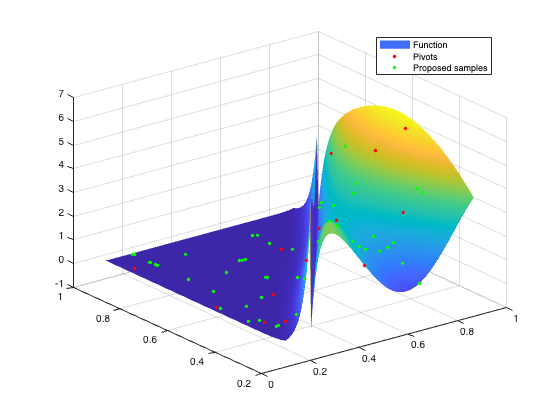

[xn,yn,sn] = create_samples(X,Y,Space,[row' col']);

draw_samples(X,Y,Space,x,y,s,xn,yn,sn);

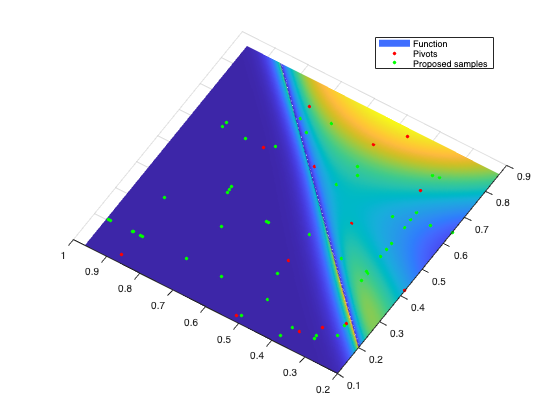

draw_samples(X,Y,Space,x,y,s,xn,yn,sn)
view([-57.28 90.00]);

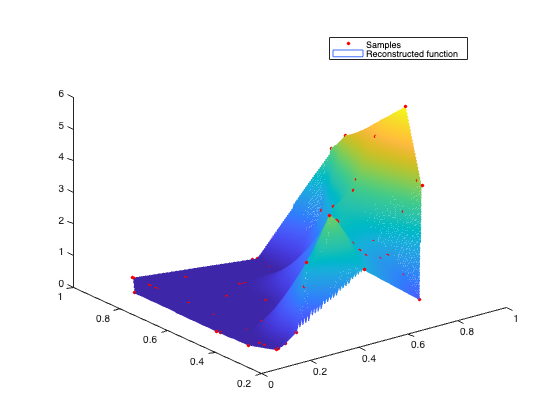

draw_interpolation(X,Y,cat(2,x,xn),cat(2,y,yn),cat(2,s,sn));

We see that the reconstruction of the function is also better.